# Homework 2

**Sebastian Aguilera Novoa**

## Part 1: Tutorial Example

### a) Theorical and CasADi solution

In order to find the optimal value $x^*$, let's derive the function to minimize and equals to zero


$$f(x)=x^2-2x \quad \Rightarrow \quad f'(x)=2x-2=0 \quad \Rightarrow \quad 
x^*=1
$$


Now, we are goint to solve the problem numerically with **CasADi** 


$$\underset{x\in \mathbb{R}}{min} \quad x^2-2x$$


clear; clc;
import casadi.*

opti = casadi.Opti();
x = opti.variable();
opti.minimize(x^2 - 2*x);

opti.solver('ipopt');

sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        1

Total number of variables............................:        1
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

xopt = sol.value(x);
if strcmp(sol.stats.return_status, 'Solve_Succeeded')      

    disp(['Optimal solution found: x = ' num2str(xopt)]);
else
    disp('Failed problem')
end

Optimal solution found: x = 1


### b) Add constraint


$$\;\qquad \underset{x\in \mathbb{R}}{min} \quad x^2-2x\\
\text { subject to }  \quad z\geq 1.5$$


opti = casadi.Opti();
x = opti.variable();
opti.minimize(x^2 - 2*x);
opti.subject_to( x>=1.5 );

opti.solver('ipopt');

sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        1
Number of nonzeros in Lagrangian Hessian.............:        1

Total number of variables............................:        1
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        1
        inequality constraints with only lower bounds:        1
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

xopt1 = sol.value(x);
disp(['x optimal, x^*= ' num2str(xopt1)]);

x optimal, x^*= 1.5


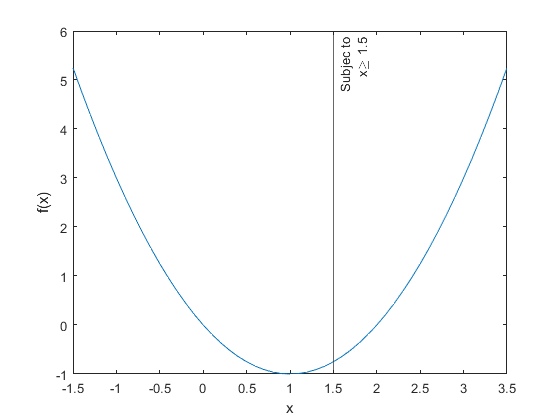

x=-1.5:0.1:3.5;

figure()
plot(x,x.^2-2*x)
xlabel('x'); ylabel('f(x)');
xline(1.5,'-',{'Subjec to','x\geq 1.5'})

These results is according to the intuition, the minimum value now is $x^*=1.5$.

### c) Bidimensional problem


$$\;\qquad \underset{x,y\in \mathbb{R}}{min} \quad x^2-2x+y^2+y\\
\text { subject to }  \quad \;z\geq 1.5\\
\quad \qquad \qquad x+y\geq 0$$


opti = casadi.Opti();
x = opti.variable();
y = opti.variable();
opti.minimize(x^2-2*x+y^2+y);
opti.subject_to( x>=1.5 );
opti.subject_to( x+y>=0 );

opti.solver('ipopt');

sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        3
Number of nonzeros in Lagrangian Hessian.............:        2

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        2
        inequality constraints with only lower bounds:        2
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

xopt2d = sol.value(x);
yopt2d = sol.value(x);
disp(['x optimal, x^*= ' num2str(xopt2d)]);

x optimal, x^*= 1.5


disp(['y optimal, y^*= ' num2str(xopt2d)]);

y optimal, y^*= 1.5


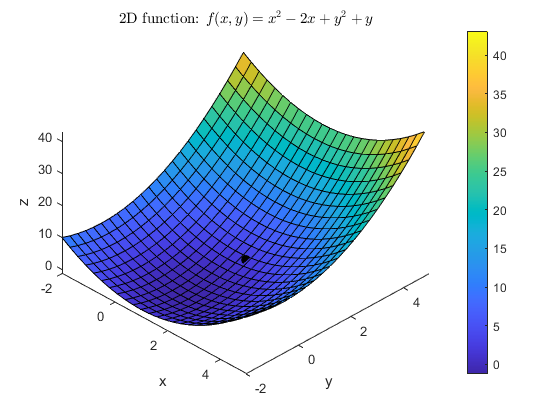

figure;
[X,Y] = meshgrid(-2:0.3:5,-2:0.3:5);
Z = X.^2-2*X+Y.^2+Y;

hold on;
surf(X,Y,Z)
title('2D function: $f(x,y)=x^2-2x+y^2+y$','interpreter','latex')
xlabel('x'); ylabel('y'); zlabel('z')
xlim([-2 5]); ylim([-2 5]);
%view(90,90)
view(45,45)
colorbar()
plot3(xopt2d,yopt2d,xopt2d^2-2*xopt2d+yopt2d.^2+yopt2d,'.','Color','black','MarkerSize',25,...
    'MarkerFaceColor','#000000');
hold off;

## Part 2: Equilibrium Position of the Catenary 

We are going to simulate a catenary as a spring chain attached to two sports at each extrem. The chain is modeled as $N$ masses connected by $N-1$springs without mass, each mass $m_i $ has a posittion $(y_i,\;z_i)$ with $i=1,\dots,N$. We are interested in finding the equilibrium position such that **minimize **the potential energy of the whole system.

The potential energy of each spring is


$$V_{el}\;(y_i,y_{i+1},z_i,z_{i+1})=\frac{1}{2}D\left( (y_i-y_{i+1})^2+(z_i-z_{i+1})^2\right)$$


for $i=1,\dots,N-1$, and a spring constant $D\in\mathbb{R}^+$. The potential energy of each mass is


$$V_g(z_i)=mgz_i$$


for $i=1,\dots,N$, $g$ is the gravity, and all masses are considered equals, $m=m_1=m_2=\cdots =m_N$. The total potential energy is given by


$$V_{chain} = \frac{1}{2}D\sum_{i=1}^{N-1} \left( (y_i-y_{i+1})^2+(z_i-z_{i+1})^2\right) + mg\sum_{i=1}^{N}z_i$$


where $y=(y_1\dots,y_N)$ and $z=(z_1\dots,z_N)$. Then, the chain minimization problem is the solution to the optimization problem


$$\qquad \underset{x, y \in \mathbb{R}^N}{min} \quad V_{\text {chain}}(y, z) \\
\text { subject to }  \quad \;\;y_1=\bar{y}_1, \quad y_N=\bar{y}_N, \\
\qquad \qquad  \quad \;\;z_1=\bar{z}_1, \quad  z_N=\bar{z}_N,$$


where $(\overline{y_1},\overline{z_1})$ and $(\overline{y_N},\overline{z_N})$ are he fixed position of the outer masses.

### a) Type of Problem

Since the problem as a objective function not lineal, it is a quadratic programming with linear constraints. Furthermore, the function and the set are convex, then the problem is a convex optimization problem.

### b) CasADi Implementation

####     Problem Formulation   

opti2 = casadi.Opti();

global N m D g

N = 40;
m = 4/N;                % kg
D = (70/40)*N;          % N/m
g = 9.81;               % m/s^2

% variables definition
Y = opti2.variable(N);    Z = opti2.variable(N); 

% objective function
Vchain = 0.5*D*(sum(diff(Y).^2) + sum(diff(Z).^2)) +  m*g*sum(Z);

% constraints
opti2.subject_to(Y(1)==-2); opti2.subject_to(Z(1)==1);
opti2.subject_to(Y(end)==2); opti2.subject_to(Z(end)==1);
opti2.minimize(Vchain)

####     Problem Solution

opti2.solver('ipopt')
sol2 = opti2.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        4
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      158

Total number of variables............................:       80
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        4
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

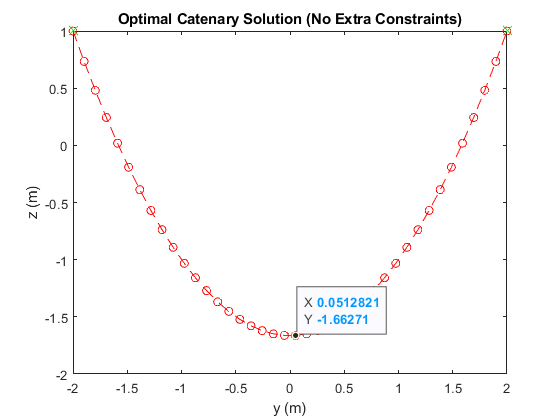

Ysol = sol2.value(Y);   Zsol = sol2.value(Z);
Plot("Optimal Catenary Solution (No Extra Constraints)", Ysol, Zsol);

ax = gca;
chart = ax.Children(3);
datatip(chart,0.05128,-1.663);

The catenary goes down to approximate 1.7 m, crossing the floor, has a mass of $40\times0.1 \; \text{kg}=4 \; \text{kg}$ and has a lenght of $4 \; \text{m}$. In the optimal solution case, the masses are distributed equally in $y$ axis but not in $z$.

diff(Ysol)'

ans =     0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026    0.1026


diff(Zsol)'

ans =    -0.2663   -0.2523   -0.2382   -0.2242   -0.2102   -0.1962   -0.1822   -0.1682   -0.1542   -0.1401   -0.1261   -0.1121   -0.0981   -0.0841   -0.0701   -0.0561   -0.0420   -0.0280   -0.0140         0    0.0140    0.0280    0.0420    0.0561    0.0701    0.0841    0.0981    0.1121    0.1261    0.1401    0.1542    0.1682    0.1822    0.1962    0.2102    0.2242    0.2382    0.2523    0.2663


### c) Linear constraints 

Adding linear constraints tho the floor, the optimization problem is


$$\qquad \underset{x, y \in \mathbb{R}^N}{min} \quad V_{\text {chain}}(y, z) \\
\text { subject to }  \quad \;\;y_1=\bar{y}_1, \quad y_N=\bar{y}_N, \\
\qquad \qquad  \quad \;\;z_1=\bar{z}_1, \quad  z_N=\bar{z}_N,\\
\qquad \qquad  \quad \;\;z_i \geq 0.5, \quad z_i-0.1y_i\geq 0.5, \quad i=2\dots,N-1$$


Here the problem is still a quadratic convex programming problem, since the constraints are again linear.

opti2c = casadi.Opti();

Y = opti2c.variable(N,1);  Z = opti2c.variable(N,1); 
Vchain = 0.5*D*(sum(diff(Y).^2) + sum(diff(Z).^2)) +  m*g*sum(Z);

opti2c.minimize(Vchain)
opti2c.subject_to(Y(1)==-2); opti2c.subject_to(Z(1)==1);
opti2c.subject_to(Y(end)==2); opti2c.subject_to(Z(end)==1);

opti2c.subject_to(Z(2:end-1) >= 0.5); 
opti2c.subject_to(Z(2:end-1)-0.1*Y(2:end-1) >= 0.5);

opti2c.solver('ipopt')
sol2c = opti2c.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        4
Number of nonzeros in inequality constraint Jacobian.:      114
Number of nonzeros in Lagrangian Hessian.............:      158

Total number of variables............................:       80
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        4
Total number of inequality constraints...............:       76
        inequality constraints with only lower bounds:       76
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

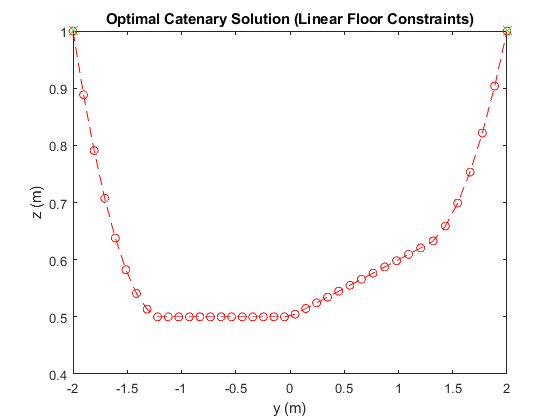

Ysolc = sol2c.value(Y);   Zsolc = sol2c.value(Z);
Plot("Optimal Catenary Solution (Linear Floor Constraints)", Ysolc, Zsolc);

The result is a catenary above the floor, $0.5 \; \text{m}$, and is accumulated to the left side, it satisfies the constraints imposed. Note that the catenary in this case is not symmetric and the masses are again equidistant in the $x$ axis but they are closer than in the previous point. 

diff(Ysolc)'

ans =     0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0975    0.0984    0.0997    0.1011    0.1025    0.1039    0.1053    0.1067    0.1081    0.1095    0.1108    0.1122    0.1135    0.1135    0.1135    0.1135    0.1135    0.1135    0.1135


diff(Zsolc)'

ans =    -0.1115   -0.0975   -0.0835   -0.0695   -0.0555   -0.0415   -0.0275   -0.0134   -0.0000   -0.0000         0         0    0.0000         0         0    0.0000         0    0.0000    0.0000    0.0000    0.0047    0.0098    0.0100    0.0101    0.0103    0.0104    0.0105    0.0107    0.0108    0.0109    0.0111    0.0112    0.0122    0.0262    0.0402    0.0542    0.0682    0.0822    0.0963


Now let's study the domain of the problem set, the linear constraints. It is important to say that the set is convex and so the problem.

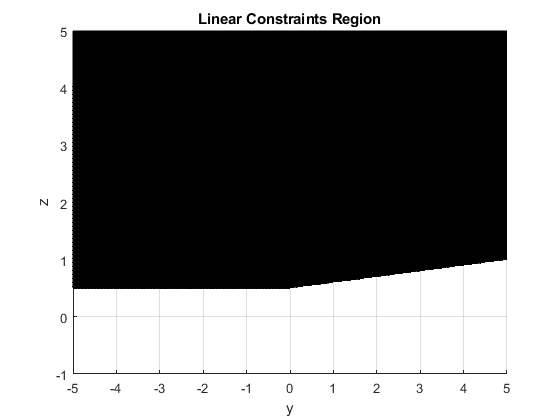

[x y] = meshgrid(-10:0.01:10);  % get 2-D mesh for x and y
cond1 = y >= 0.5;  % check conditions for these values
cond2 = y-0.1*x >= 0.5;
cond1 = double(cond1);  % convert to double for plotting
cond2 = double(cond2);
cond1(cond1 == 0) = NaN;  % set the 0s to NaN so they are not plotted
cond2(cond2 == 0) = NaN;
cond = cond1.*cond2;  % multiply the two condaces to keep only the common points
surf(x,y,cond)
view(0,90)    % change to top view
ylim([-1 5]); xlim([-5 5]);
xlabel('y'); ylabel('z');
title('Linear Constraints Region')

### d) Nolinear constraints 

Adding non linear constraints to the floor. Now the problem is


$$\qquad \underset{x, y \in \mathbb{R}^N}{min} \quad V_{\text {chain}}(y, z) \\
\text { subject to }  \quad \;\;y_1=\bar{y}_1, \quad y_N=\bar{y}_N, \\
\qquad \qquad  \quad \;\;z_1=\bar{z}_1, \quad  z_N=\bar{z}_N,\\
\qquad \qquad  \quad \;\;z_i \geq -0.2 +0.1y_i^2, \quad i=2\dots,N-1$$


with these new constraints the problem is still convex, since the region of the domain is a convex set. Again, the problem is a quadratic contrained optimization problem. In order to check its convexity, let's study the domain region defined by the final inequality

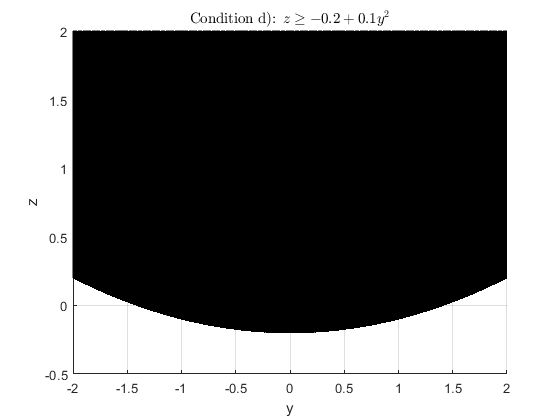

[x y] = meshgrid(-2:0.001:2);  % get 2-D mesh for x and y
cond1 = y >= -0.2+0.1*x.^2;  % check conditions for these values
cond1 = double(cond1);  % convert to double for plotting
cond1(cond1 == 0) = NaN;  % set the 0s to NaN so they are not plotted
surf(x,y,cond1)
xlabel("y"); ylabel("z"); 
title("Condition d): $z \geq -0.2 +0.1y^2$",'interpreter','latex');
view(0,90)    % change to top view

### e) Nolinear constraints 

Changing the non linear constraints to the floor. Now the problem is


$$\qquad \underset{x, y \in \mathbb{R}^N}{min} \quad V_{\text {chain}}(y, z) \\
\text { subject to }  \quad \;\;y_1=\bar{y}_1, \quad y_N=\bar{y}_N, \\
\qquad \qquad  \quad \;\;z_1=\bar{z}_1, \quad  z_N=\bar{z}_N,\\
\qquad \qquad  \quad \;\;z_i \geq -y_i^2, \quad i=2\dots,N-1$$


Now the problem is different, the new inequality is a not convex set and so the whole problem is now a not convex problem. Although the objective function remains the same the inequalities add an instability as there are now  more minimums, this will be shown by initializing the problem with different initial values.

Let's look the domain region. Note that this set is not convex.

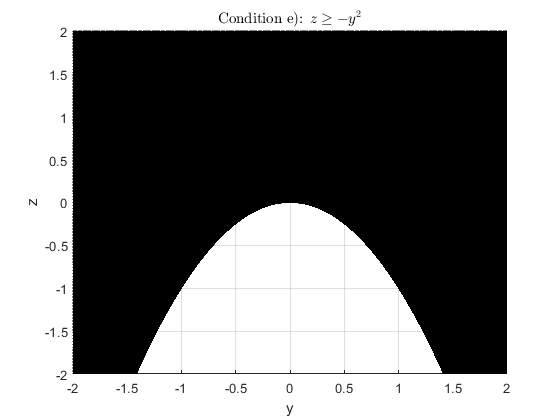

[x y] = meshgrid(-2:0.001:2);  % get 2-D mesh for x and y
cond1 = y >= -x.^2;  % check conditions for these values
cond1 = double(cond1);  % convert to double for plotting
cond1(cond1 == 0) = NaN;  % set the 0s to NaN so they are not plotted
surf(x,y,cond1)
xlabel("y"); ylabel("z"); 
title("Condition e): $z \geq -y^2$",'interpreter','latex');
view(0,90)    % change to top view

### f) CasADi solution

####     i. Solution item d)

pd = CatenaryD(zeros(N,1),zeros(N,1));

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        4
Number of nonzeros in inequality constraint Jacobian.:       76
Number of nonzeros in Lagrangian Hessian.............:      158

Total number of variables............................:       80
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        4
Total number of inequality constraints...............:       38
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       38

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

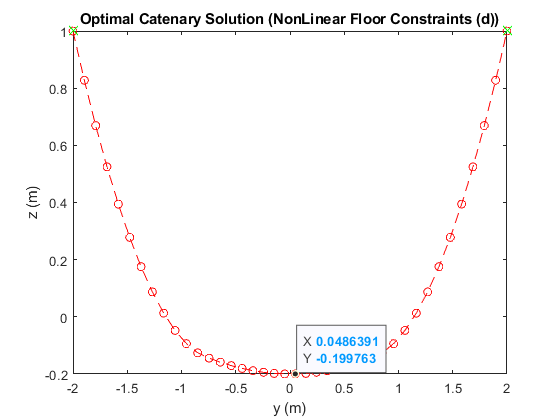

ax2 = gca;
chart2 = ax2.Children(3);
datatip(chart2,0.04864,-0.1998);

changing both initial vector to a vector of ones

pd1 = CatenaryD(ones(N,1),ones(N,1));

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        4
Number of nonzeros in inequality constraint Jacobian.:       76
Number of nonzeros in Lagrangian Hessian.............:      158

Total number of variables............................:       80
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        4
Total number of inequality constraints...............:       38
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       38

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

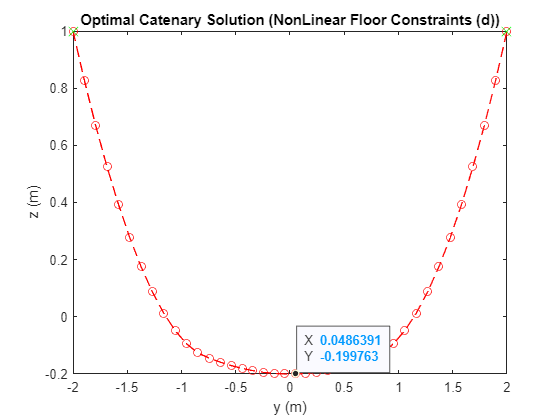

ax3 = gca;
chart3 = ax3.Children(3);
datatip(chart3,0.04864,-0.1998);

Note that if the initial vector is changed the result does not change, so there is just one minimum and the solution is stable.

####     ii. Solution item e)

Let's study the problem by initializing it with vectors of zeros

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        4
Number of nonzeros in inequality constraint Jacobian.:       76
Number of nonzeros in Lagrangian Hessian.............:      158

Total number of variables............................:       80
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        4
Total number of inequality constraints...............:       38
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       38

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

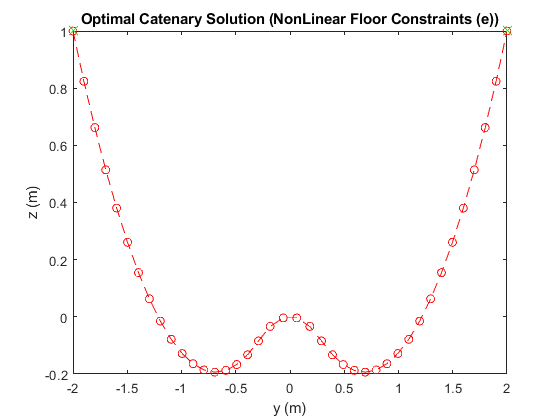

Ysol = 
    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006    0.1006

Zsol = 
   -0.1759   -0.1619   -0.1479   -0.1339   -0.1198   -0.1058   -0.0918   -0.0778   -0.0638



pe1 = CatenaryE(zeros(N,1),zeros(N,1));

The result is a catenary with two local minimums and one local maximum , it falls to $20 \;\text{cm}$ crossing the floorl. Now, let's change the initial values to vector of ones

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        4
Number of nonzeros in inequality constraint Jacobian.:       76
Number of nonzeros in Lagrangian Hessian.............:      158

Total number of variables............................:       80
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        4
Total number of inequality constraints...............:       38
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       38

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

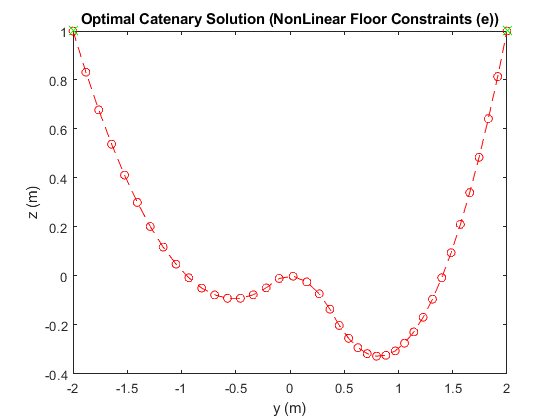

Ysol = 
    0.1186    0.1186    0.1186    0.1186    0.1186    0.1186    0.1186    0.1186    0.1186

Zsol = 
   -0.1680   -0.1540   -0.1400   -0.1260   -0.1119   -0.0979   -0.0839   -0.0699   -0.0559



pe2 = CatenaryE(ones(N,1),ones(N,1));

Again, the result is a catenery with two locals minimums and one locals maximum but in this case the catenary is accumulated to the right side, the result has changed. 

Finally, let's change the initial vector to vectors of negative ones

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        4
Number of nonzeros in inequality constraint Jacobian.:       76
Number of nonzeros in Lagrangian Hessian.............:      158

Total number of variables............................:       80
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        4
Total number of inequality constraints...............:       38
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       38

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

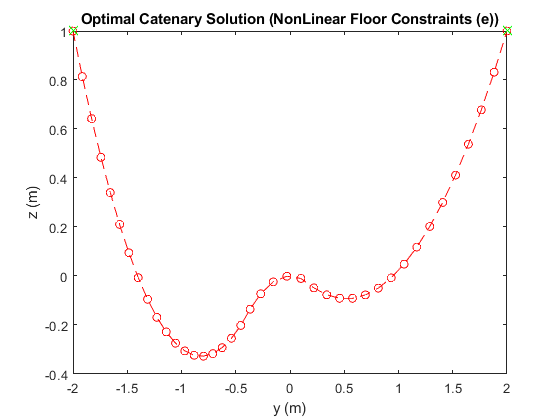

Ysol = 
    0.0859    0.0859    0.0859    0.0859    0.0859    0.0859    0.0859    0.0859    0.0859

Zsol = 
   -0.1859   -0.1719   -0.1579   -0.1438   -0.1298   -0.1158   -0.1018   -0.0878   -0.0738



pe3 = CatenaryE(-ones(N,1),-ones(N,1));

Again, the result is a catenery with two locals minimums and one locals maximum but in this case the catenary is accumulated to the left side, the result has changed again and it falls to $30 \;\text{cm}$, crossing the floor. 

Note that when any initial vector is changed the solution changes. This means that this problem is sensity to change the initial vectors, then there is not just a minimum. 

**Note:**

It is important to mention that when the mass $m$ increase the catenary falls lower and for a certain $m$ the problem begins to present inestabilities with the nonlinear constraints.

mc = N/4;                % kg

opti2caotic = casadi.Opti();

Y = opti2caotic.variable(N);    Z = opti2caotic.variable(N); 

Vchain = 0.5*D*(sum(diff(Y).^2) + sum(diff(Z).^2)) +  mc*g*sum(Z);

opti2caotic.subject_to(Y(1)==-2); opti2caotic.subject_to(Z(1)==1);
opti2caotic.subject_to(Y(end)==2); opti2caotic.subject_to(Z(end)==1);
opti2caotic.subject_to(Z(2:end-1) >= -Y(2:end-1).^2);
opti2caotic.minimize(Vchain)

opti2caotic.solver('ipopt')
sol2 = opti2caotic.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        4
Number of nonzeros in inequality constraint Jacobian.:       76
Number of nonzeros in Lagrangian Hessian.............:      158

Total number of variables............................:       80
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        4
Total number of inequality constraints...............:       38
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       38

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

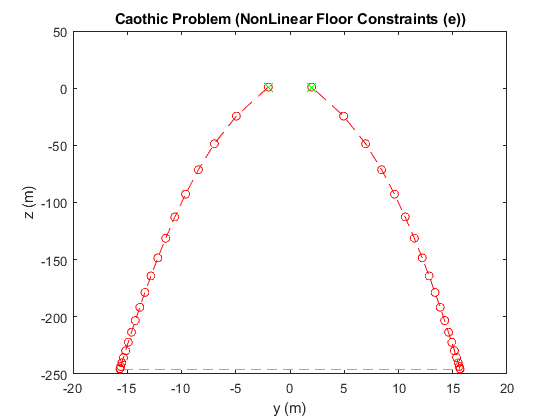

Y= opti2caotic.value(Y);     Z = opti2caotic.value(Z);
Plot("Caothic Problem (NonLinear Floor Constraints (e))", Y, Z);

### Auxiliar Functions

function p=Plot(ti, Y, Z)
    figure;
    p=plot(Y,Z,'--or'); hold on;
    plot(-2,1,'xg','MarkerSize',10);
    plot(2,1,'xg','MarkerSize',10);
    xlabel('y (m)'); ylabel('z (m)');
    title(ti);          hold off;
end

function [p] = CatenaryD(Y0,Z0)
    global N m D g
    opti2d = casadi.Opti();

    Y = opti2d.variable(N,1); 
    Z = opti2d.variable(N,1); 
    
    opti2d.set_initial(Y,Y0);
    opti2d.set_initial(Y,Z0);
    
    Vchain = 0.5*D*(sum(diff(Y).^2) + sum(diff(Z).^2)) +  m*g*sum(Z);
    
    opti2d.minimize(Vchain)
    opti2d.subject_to(Y(1)==-2); opti2d.subject_to(Z(1)==1);
    opti2d.subject_to(Y(end)==2); opti2d.subject_to(Z(end)==1);
    
    opti2d.subject_to(Z(2:end-1) >= -0.2+0.1*Y(2:end-1).^2);
    
    opti2d.solver('ipopt')
    sol2d = opti2d.solve();
    
    Ysold = opti2d.value(Y);     Zsold = opti2d.value(Z);

    p = Plot("Optimal Catenary Solution (NonLinear Floor Constraints (d))", Ysold, Zsold);
    disp("Ysol = "); disp(diff(Ysold(1:10))');
    disp("Zsol = "); disp(diff(Zsold(1:10))');
end


function [p] = CatenaryE(Y0,Z0)
    global N m D g
    opti2e = casadi.Opti();

    Y = opti2e.variable(N,1); 
    Z = opti2e.variable(N,1); 
    
    opti2e.set_initial(Y,Y0);
    opti2e.set_initial(Y,Z0);
    
    Vchain = 0.5*D*(sum(diff(Y).^2) + sum(diff(Z).^2)) +  m*g*sum(Z);
    
    opti2e.minimize(Vchain)
    opti2e.subject_to(Y(1)==-2); opti2e.subject_to(Z(1)==1);
    opti2e.subject_to(Y(end)==2); opti2e.subject_to(Z(end)==1);
    
    opti2e.subject_to(Z(2:end-1) >= -Y(2:end-1).^2);
    
    opti2e.solver('ipopt')
    sol2e = opti2e.solve();
    
    Ysole = opti2e.value(Y);     Zsole = opti2e.value(Z);

    p = Plot("Optimal Catenary Solution (NonLinear Floor Constraints (e))", Ysole, Zsole);
    disp("Ysol = "); disp(diff(Ysole(1:10))'); 
    disp("Zsol = "); disp(diff(Zsole(1:10))');
end

This work was made using [CasADi](https://www.web.casadi.org).